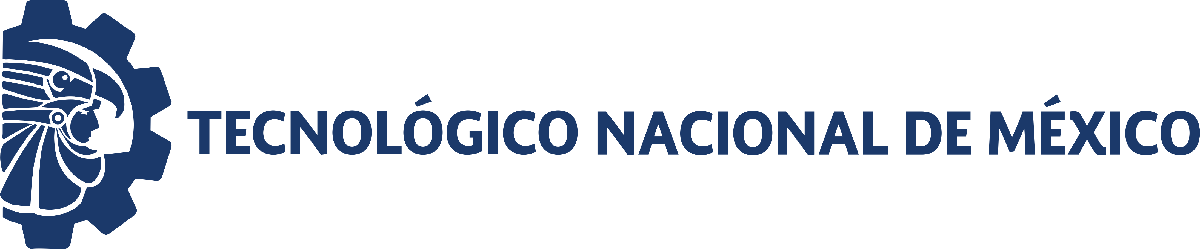                                 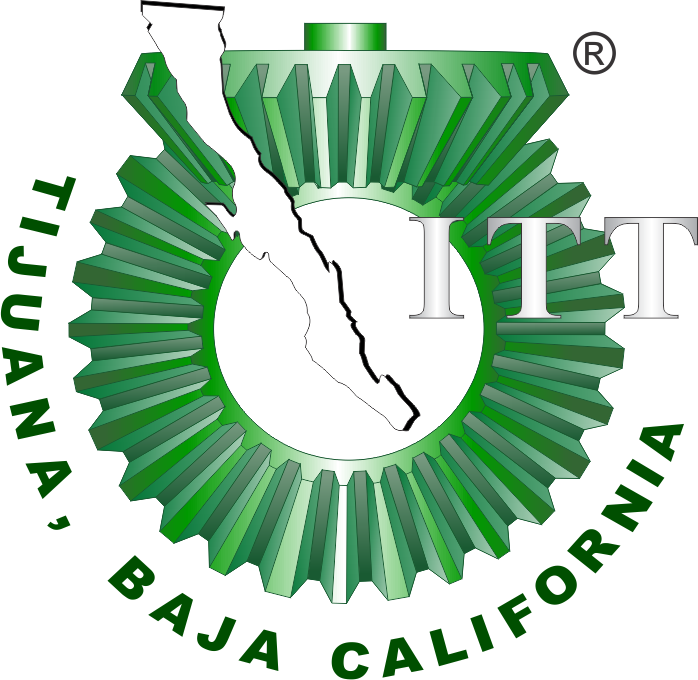

# Práctica 4 : Modelado y control del sistema endocrino 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

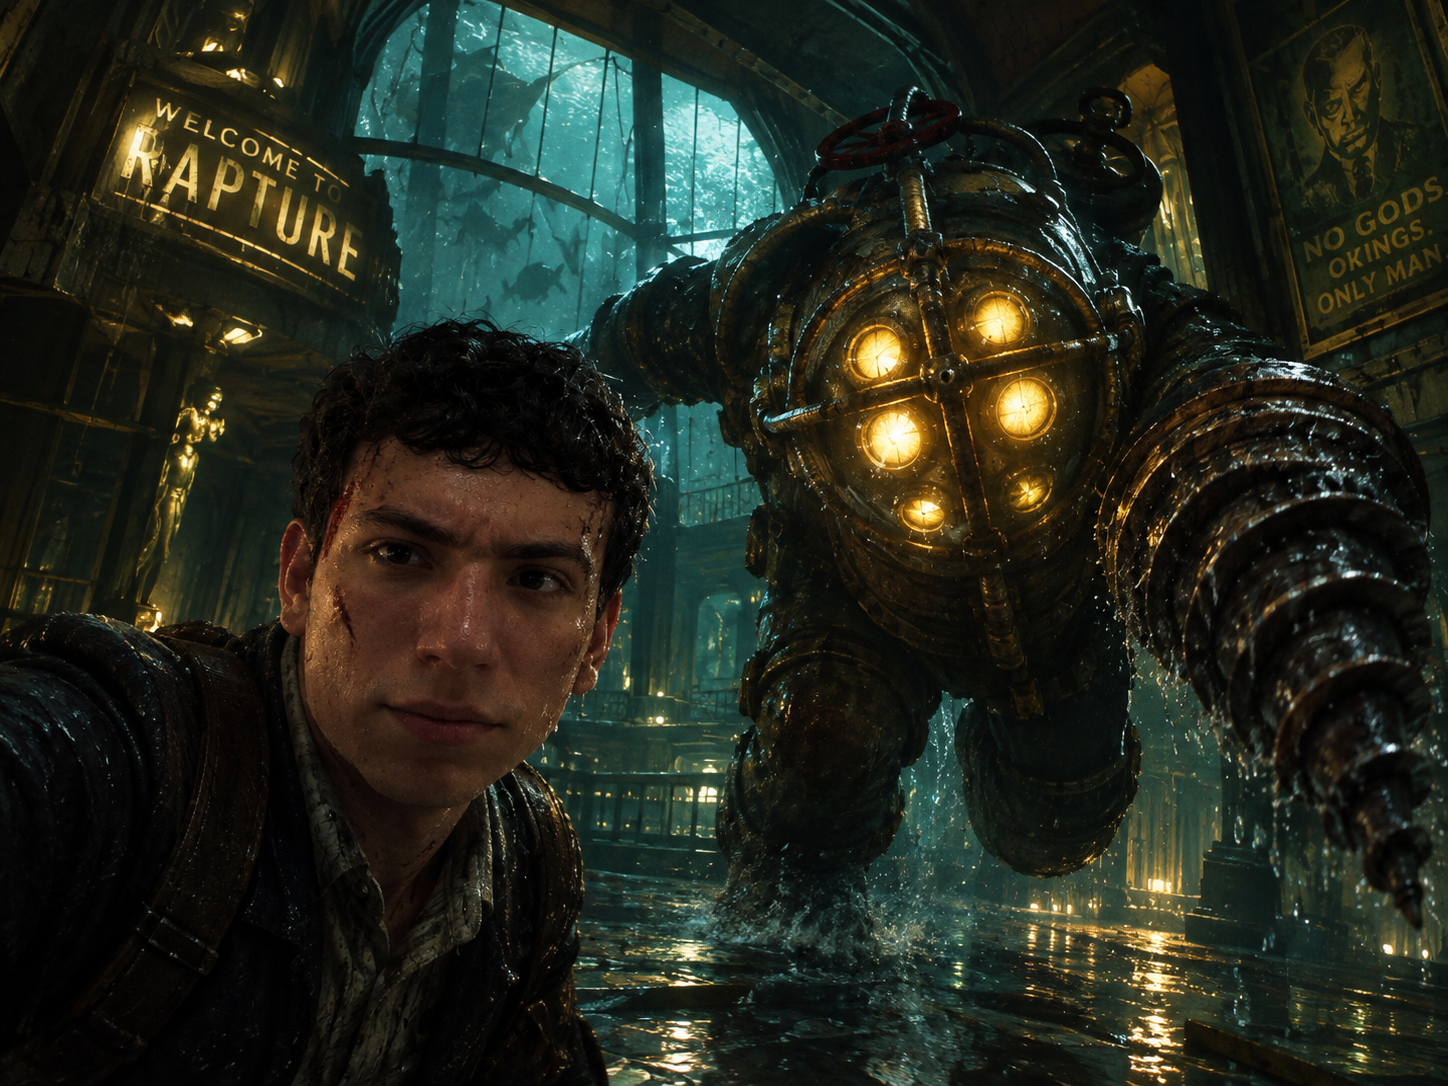

Nombre del alumno: Josue Raul Guerrero Peñaloza

Número de control: 24210583

Correo institucional: l24210583**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistema2020_4')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-2';
x = sim('sistema2020_4',parameters);


## Respuesta en Caso

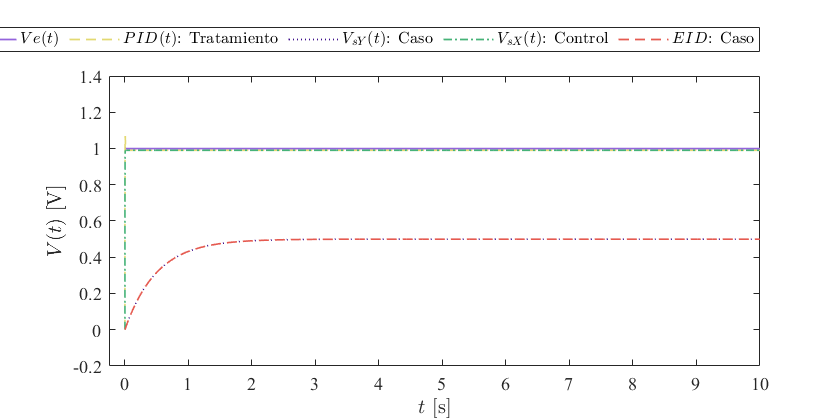

plotsignals(x.t, x.Ve, x.PID, x.Vsy, x.Vsx,x.EIDC,'Caso')

## Funcion: Respuestas de la simulacion

function plotsignals (t,x1,x2,x3,x4,x5,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = ([149, 100, 221])/256;
    clr2 = ([228, 218, 114])/256;
    clr3 = ([62, 15, 141])/256;
    clr4 = ([70, 180, 120]) / 256;
    clr5 = ([230, 90, 80]) / 256;
    order = [clr1; clr2; clr3; clr4; clr5]; colororder(order)
    xlabel('$t$ [s]','Interpreter','latex')
    ylabel('$V(t)$ [V]','Interpreter','latex')
    xlim([-0.25 10]); xticks(0:1:10)

    if signal == "Caso"
        plot(t,x1,'-',t,x2,'--',t,x3,':',t,x4,'-.',t,x5,'--','LineWidth',1)
        L = legend('$Ve(t)$','$PID(t)$: Tratamiento','$V_{sY}(t)$: Caso','$V_{sX}(t)$: Control','$EID$: Caso');
    end

    set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
    ylim([-0.2 1.4]); yticks(-0.2:0.2:1.4)

    exportgraphics(gcf,[signal,'_matlab.pdf'],'ContentType','vector')
end